# Project Digital Image Processing

## Benny Aman 205873599

## Sapir Seluk 308308980

close all;
clear all;
clc;

`בתור התחלה נקרא את התמונה`

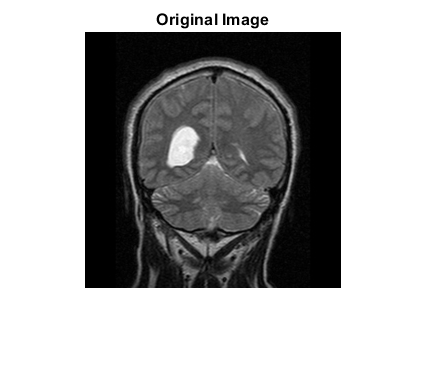

im = imread('brain1.jpg');
figure,imshow(im),title('Original Image')

`נעביר את התמונה לסוג אפור`

[m,n]=size(im);
Igray=im2gray(im);

`נעביר כעת את התמונה במסנן מסוג היי פס`

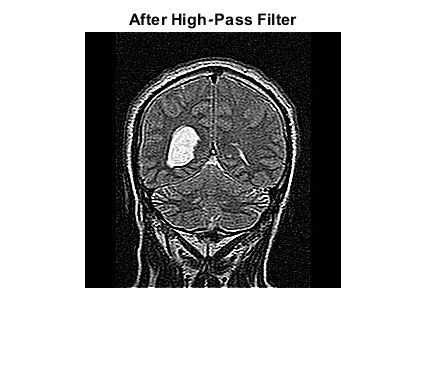

kernel = -1*ones(3);
kernel(2,2) = 9;
echancedImage = imfilter(Igray, kernel);
figure,imshow(echancedImage),title('After High-Pass Filter');

`כעת נחדד את התמונה`

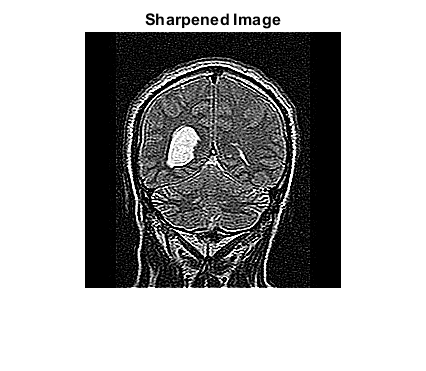

Ishap = imsharpen(echancedImage);
figure, imshow(Ishap); title('Sharpened Image');

`נעביר את התמונה במסנן מסוג מדיאן בכדי להיפטר מהרעשים`

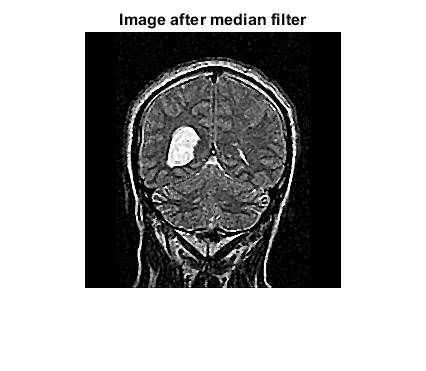

Imed=medfilt2(Ishap,[3,3]);
figure,imshow(Imed),title('Image after median filter')

`נהפוך כעת את התמונה לבינארית`

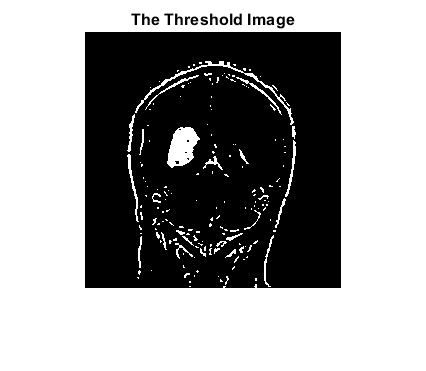

bw = im2bw(Imed,0.7); 
figure,imshow(bw),title('The Threshold Image')

`נתחיל כעת להשתמש בשיטות המורפולוגיות`

`כעת נזהה את האובייקט שלנו`

label = bwlabel(bw);

`נחשב כעת את מיקום האובייקט`

stats = regionprops(label,'Solidity','Area');
density = [stats.Solidity];
area = [stats.Area];
high_dense_area = density>0.5;
max_area = max(area(high_dense_area));
tumor_label = find(area==max_area);
tumor=ismember(label,tumor_label);

`נבנה כעת את האובייקט מחדש`

se=strel('square',5);

` Dilation - נבצע כעת הרחבת פיקסלים כלומר נבצע `

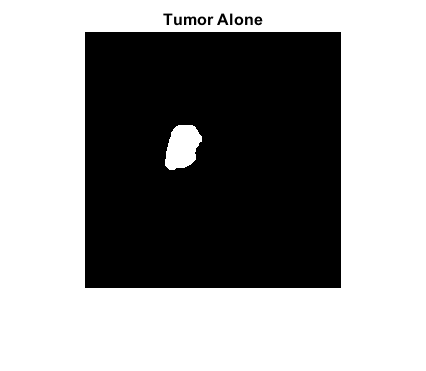

tumor = imdilate(tumor,se);
figure,imshow(tumor,[]),title('Tumor Alone');

`כעת נחפש רק את גבולות האובייקט שלנו`

[B,L]=bwboundaries(tumor,'noholes');
figure,imshow(Imed,[]);
hold on


`כעת נסמן את הגידול באמצעות קו אדום בעובי 2`

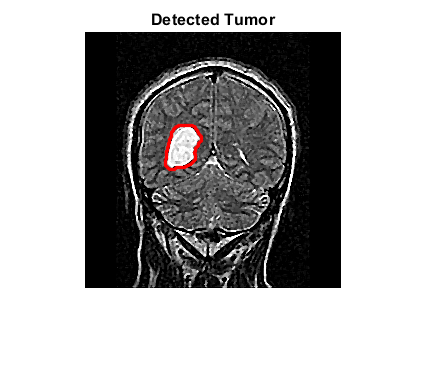

for i=1:length(B)
    plot(B{i}(:,2),B{i}(:,1), 'r' ,'linewidth',2);
    title('Detected Tumor');
end
hold off